**0. Preparation**

clear all, close all,clc
load('ch1RestMotion1234.mat');

% variables are available
% ch1Motion1 4001x1
% ch1Motion2 4001x1
% ch1Motion3 4001x1
% ch1Motion4 4001x1
% ch1Rest    5000x1

**1. Data Conn**

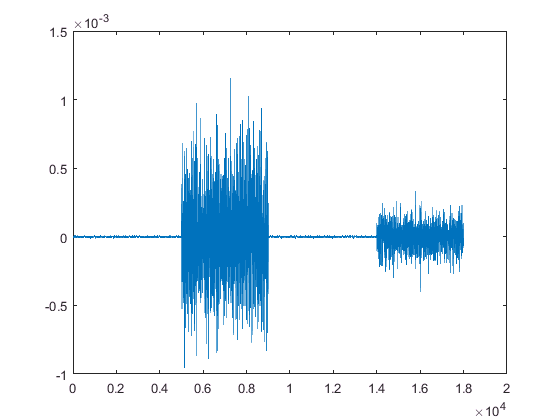

x1 = [ch1Rest;ch1Motion1;ch1Rest;ch1Motion2];
plot(x1)

**2. Denoising with different Methods**

    2.1 wden - denoising

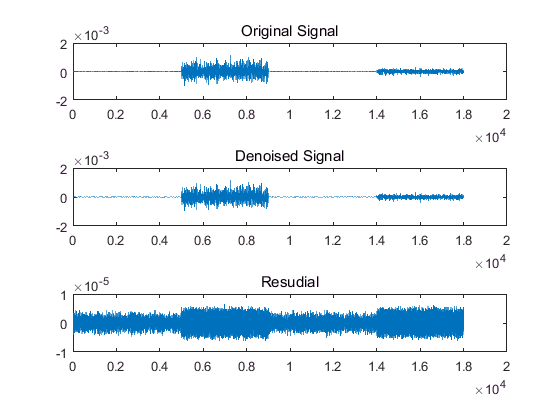

xd1 = wden(x1, 'heursure','s','mln',3,'sym8');
figure;
subplot(311);plot(x1);title('Original Signal');
subplot(312);plot(xd1);title('Denoised Signal');
subplot(313);plot(x1-xd1);title('Resudial');

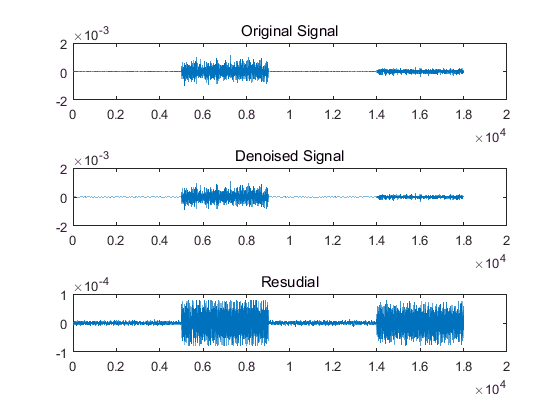

xd1 = wden(x1, 'sqtwolog','s','mln',6,'haar');
figure;
subplot(311);plot(x1);title('Original Signal');
subplot(312);plot(xd1);title('Denoised Signal');
subplot(313);plot(x1-xd1);title('Resudial');

3. Test wavename available

xd1 = wden(x1, 'sqtwolog','s','mln',2,'coif5');
% haar
% sym8
% sym5
% db5
% db2
% coif5